对内联表查询进行图论优化

此函数通常与Select结合使用，在执行查询之前对待查询的表进行图论优化，剪除与查询无关的列和表，将表按照内联的顺序排列。并检查待查询表能否通过键列内联，以及感兴趣的列是否在表中有出现。这里的键列，指的是在表中不具有重复值的列；即，如果表中某列无重复值，该列称为该表的键列。

图论优化是指，将所有表和列作为节点，将“表包含列”的关系作为边画一张图。这样，所有的表节点连接的都是列节点，所有的列节点连接的都是表节点。一个表可能有多个列节点连接，一个列也可能有多个表节点连接。如果一个列仅属于一个表，称之为孤立列，否则称为连接列。如果一个表仅有一个非键的连接列，称之为定义表，否则称为关系表。

一般来说，关系表不如定义表重要，因此它常成为图论优化的对象。在检索两个感兴趣的列之间所有的连通路径时，会先检索那些不含关系表的路径。只要检索到一条这样的路径，就不会再去检索那些含有关系表的路径；而如果一个表不在任何两个感兴趣的列之间的路径上，这个表就会被优化掉。因此，除非一个关系表是某两个感兴趣的列之间的必经路径，否则这个关系表就会被优化掉；而定义表不同，只要它存在于任何两个感兴趣的列之间的任意一条路径上，它就不会被优化掉。如果你不希望关系表被优化掉，可以指定MATLAB.Flags.DisableLinkerOptimize旗帜，这样的话关系表和定义表将被平等对待。

## 语法

## 示例

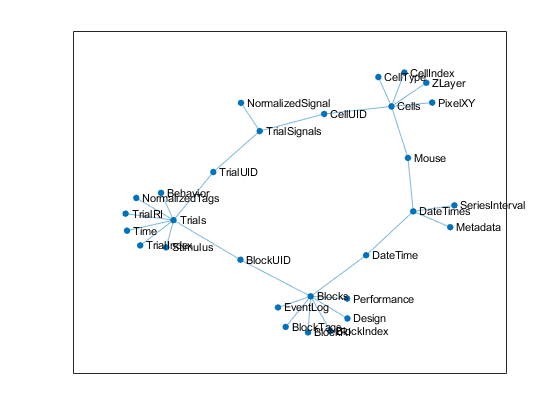

根据定义，Mouse TrialUID BlockUID CellUID 都是连接列，其它列是孤立列；TrialSignals是关系表，其它表是定义表。

## 输入参数

Tables，要优化查询的多个表，可以是以下类型，将对TableGraph返回值产生影响：

- (1,:)cell，每个元胞内一个表，TableGraph中的表节点将随机生成一个UID作为节点名称

- (1,1)struct，每个结构体字段一个表，TableGraph中的表节点将以结构体字段名作为节点名称。注意，这要求表名称不能跟所有输入表中的任何列名重复。

ColumnsOfInterest(1,:)string，感兴趣的列，包括所有应当在查询结果表中显示的列和作为查询条件的列。

Flags(1,:)MATLAB.Flags，额外功能旗帜，可以组合指定，可选以下旗帜：

- DisableLoops，如果指定此旗帜，将检查表内联图

- DisableLinkerOptimize，如果指定此旗帜，将不会对关系表和定义表进行区分优化。

## 返回值

OptimizedTables(1,:)cell，每个元胞内包含一个优化后的表。所有非键列如果不在感兴趣的列中将被优化掉。所有不在感兴趣的列的内联路径上的表将被优化掉。表经过排序，确保可以按此顺序逐一内联。

TableGraph(1,1)graph，优化后的表内联图。获取此返回值可用于对查询做更多自定义优化和检查，例如手动检查图中是否存在循环。如果不输出此返回值，将在发现循环时发出警告。如果指定MATLAB.Flags.DisableLoops旗帜，将在发现循环时抛出异常，不返回值。此图的Nodes表将含有一个TableIndex列，用0表示对应节点是列，用正数表示对应节点是OptimizedTables中的第几个表。

**See also** [innerjoin](matlab:doc innerjoin) [MATLAB.DataTypes.Select](matlab:doc MATLAB.DataTypes.Select)

function [OptimizedTables,TableGraph] = OptimizeQueryGraph(Tables,ColumnsOfInterest,Flags)
TableGraph=graph;
HasTableName=isstruct(Tables);
if HasTableName
	TableNames=fieldnames(Tables);
	Tables=struct2cell(Tables);
	NumTables=numel(Tables);
else
	NumTables=numel(Tables);
	TableNames=matlab.lang.internal.uuid(NumTables,1);
end
warning off MATLAB:table:RowsAddedExistingVars
for TableIndex=1:NumTables
	Name=TableNames(TableIndex);
	try
		TableGraph=TableGraph.addnode(table(Name,TableIndex)).addedge(Name,Tables{TableIndex}.Properties.VariableNames);
	catch ME
		if ME.identifier=="MATLAB:structRefFromNonStruct"
			MATLAB.Lang.MatlabException.Input_not_tabular.Throw(sprintf('第%u个输入不是表',TableIndex));
		else
			ME.rethrow;
		end
	end
end
DisableLoops=false;
if nargin>1
	NumColumns=numel(ColumnsOfInterest);
	switch NumColumns
		case 0
			OptimizedTables=cell(1,0);
			TableGraph=graph;
			return;
		case 1
			TableGraph=TableGraph.subgraph([ColumnsOfInterest;TableGraph.neighbors(ColumnsOfInterest)]);
			TableLogical=TableGraph.Nodes.TableIndex>0;
			OptimizedTables=Tables(TableGraph.Nodes.TableIndex(TableLogical));
			TableGraph.Nodes.TableIndex(TableLogical)=1:numel(OptimizedTables);
			return;
	end
	if nargin>2
		Flags=num2cell(ismember([MATLAB.Flags.DisableLoops,MATLAB.Flags.DisableLinkerOptimize],Flags));
		[DisableLoops,LinkerOptimize]=Flags{:};
		LinkerOptimize=~LinkerOptimize;
	else
		LinkerOptimize=true;
	end
	if LinkerOptimize
		IsLinker=cellfun(@(Table)sum(cellfun(@(ColumnName)TableGraph.degree(ColumnName)>1&&numel(unique(Table.(ColumnName)))<numel(Table.(ColumnName)),Table.Properties.VariableNames)),Tables)>1;
	end
	PathNodes=MATLAB.Containers.Vector;
	ColumnNodes=TableGraph.findnode(ColumnsOfInterest);
	if ~all(ColumnNodes)
		MATLAB.Lang.MatlabException.Column_not_found_in_tables.Throw(join(ColumnsOfInterest(~ColumnNodes),' '));
	end
	for C1=1:NumColumns-1
		for C2=C1+1:NumColumns
			try
				Paths=TableGraph.allpaths(ColumnNodes(C1),ColumnNodes(C2));
			catch ME
				if ismember(ME.identifier,["MATLAB:graphfun:graph:UnknownNodeName","MATLAB:graphfun:findnode:NoNames"])
					MATLAB.Lang.MatlabException.Column_not_found_in_tables.Throw(join(setdiff(ColumnsOfInterest,TableGraph.Nodes.Name),' '));
				else
					ME.rethrow;
				end
			end
			if isempty(Paths)
				MATLAB.Lang.MatlabException.Two_columns_not_connected.Throw(join(ColumnsOfInterest([C1 C2]),' '));
			else
				if LinkerOptimize
					NumPaths=numel(Paths);
					NumLinkers=zeros(NumPaths,1);
					for P=1:NumPaths
						PathTables=TableGraph.Nodes.TableIndex(Paths{P});
						%统计关系表的个数，选择关系表最少的路径
						NumLinkers(P)=sum(IsLinker(PathTables(PathTables>0)));
					end
					Paths(NumLinkers>min(NumLinkers))=[];
				end
				PathNodes.PushBack(Paths);
			end
		end
	end
	TableGraph=TableGraph.subgraph(unique([PathNodes.Data{:}]));
end
%此处用&&确保仅在必要时检查循环
if DisableLoops&&TableGraph.hascycles
	Cycle=TableGraph.allcycles(MaxNumCycles=1);
	MATLAB.Lang.MatlabException.Query_graph_contains_cycles.Throw(string(join(Cycle{1},'→')));
elseif nargout<2&&TableGraph.hascycles
	Cycle=TableGraph.allcycles(MaxNumCycles=1);
	MATLAB.Lang.MatlabException.Query_graph_contains_cycles.Warn(string(join(Cycle{1},'→')));
end
TableNodes=TableGraph.bfsearch(1);
TableIndex=TableGraph.Nodes.TableIndex(TableNodes);
TableLogical=TableIndex>0;
OptimizedTables=arrayfun(@(Node,Index)Tables{Index}(:,TableGraph.Nodes.Name(TableGraph.neighbors(Node))),TableNodes(TableLogical),TableIndex(TableLogical),UniformOutput=false);